# ENAE311H - HW06

% Clear history
clear;
clc;

% Set LaTeX as Interpreter for text labels
list_factory = fieldnames(get(groot,'factory'));
index_interpreter = find(contains(list_factory,'Interpreter'));
for i = 1:length(index_interpreter)
    default_name = strrep(list_factory{index_interpreter(i)},'factory','default');
    set(groot, default_name,'latex');
end

## Problem 1

% Constants
R_air = 287; % J/(kg*K)
gamma_air = 1.4; % unitless

% Given
y_1 = 3e4; % ft
p_1 = 30e3; % Pa
T_1 = 230; % K
T_0_1 = 333.5; % K

% Vars
syms R gamma p p_0 T T_0 v

### Part A

% Solution
v_eqn = v == (2*gamma*R*(T_0-T)/(gamma-1))^(1/2)

$$v\_eqn = v=\sqrt{-\frac{2\,R\,\gamma \,\left(T-T_{0}\right)}{\gamma -1}}$$

p_0_eqn = p_0 == p*(1+(gamma-1)/(2*gamma*R*T)*v^2)^(gamma/(gamma-1))

$$p\_0\_eqn = p_{0}=p\,{\left(\frac{0.5000\,v^{2}\,\left(\gamma -1\right)}{R\,T\,\gamma }+1\right)}^{\frac{\gamma }{\gamma -1}}$$


v_1 = solve(subs(v_eqn, [ R gamma T T_0 ], [ R_air gamma_air T_1 T_0_1 ]), v)

$$v\_1 = 455.9951$$

p_0_1 = solve(subs(p_0_eqn, [ R gamma p T v ], [ R_air gamma_air p_1 T_1 v_1 ]), p_0)

$$p\_0\_1 = 1.1013e+05$$

### Part B

% Given
p_0_1 = 45.73e3; % Pa

% Solution
v_eqn = v == (2*gamma*R*T/(gamma-1)*((p_0/p)^((gamma-1)/gamma)-1))^(1/2)

$$v\_eqn = v=\sqrt{\frac{2\,R\,T\,\gamma \,\left({\left(\frac{p_{0}}{p}\right)}^{\frac{\gamma -1}{\gamma }}-1\right)}{\gamma -1}}$$

v_1 = solve(subs(v_eqn, [ R gamma p p_0 T ], [ R_air gamma_air p_1 p_0_1 T_1 ]), v)

$$v\_1 = 243.1960$$

## Problem 2

% Constants
R_air = 287; % J/(kg*K)
gamma_air = 1.4; % unitless

% Given
M_i = zeros(3, 1); % unitless
nu_i = zeros(3, 1); % deg

M_i(1) = 2.4; % unitless
M_i(3) = 3; % unitless

% Vars
syms R gamma M nu nu_a nu_b theta beta

% Solution
nu_eqn = nu == ((gamma+1)/(gamma-1))^(1/2)*atan(((gamma-1)/(gamma+1)*(M^2-1))^(1/2))-atan((M^2-1)^(1/2))

$$nu\_eqn = \nu =\mathrm{atan}\left(\sqrt{\frac{\left(M^{2}-1\right)\,\left(\gamma -1\right)}{\gamma +1}}\right)\,\sqrt{\frac{\gamma +1}{\gamma -1}}-\mathrm{atan}\left(\sqrt{M^{2}-1}\right)$$

theta_eqn = theta == -1*(nu_b - nu_a)

$$theta\_eqn = \theta =\nu_{a}-\nu_{b}$$

tbm_eqn = tan(theta) == 2*cot(beta)*(M^2*sin(beta)^2-1)/(M^2*(gamma+cos(2*beta))+2)

$$tbm\_eqn = \tan\left(\theta \right)=\frac{2\,\cot\left(\beta \right)\,\left(M^{2}\,{\sin\left(\beta \right)}^{2}-1\right)}{\left(\gamma +\cos\left(2\,\beta \right)\right)\,M^{2}+2}$$


nu_soln = solve(subs(nu_eqn, [ R gamma M ], [ R_air gamma_air M_i(1) ]), nu);
nu_i(1) = nu_soln;
nu_soln = solve(subs(nu_eqn, [ R gamma M ], [ R_air gamma_air M_i(3) ]), nu);
nu_i(3) = nu_soln;

theta_soln = solve(subs(theta_eqn, [ nu_a nu_b ], [ nu_i(1) nu_i(3) ]), theta);
theta_1 = theta_soln;

beta_soln = solve(subs(tbm_eqn, [ R gamma M theta ], [ R_air gamma_air M_i(1) theta_1 ]), beta);
beta_1 = abs(beta_soln);

theta_1 = rad2deg(theta_1)

$$theta\_1 = -13.0108$$

beta_1 = rad2deg(beta_1)

$$beta\_1 = 36.0552$$

## Problem 3

% Constants
R_air = 287; % J/(kg*K)
gamma_air = 1.4; % unitless

% Given
n = 3; % num shocks
y = 10e3; % m
M_i = zeros(n+1, 1); % unitless
p_i = zeros(n+1, 1); % Pa
T_i = zeros(n+1, 1); % K
p_0_i = zeros(n+1, 1); % Pa
T_0_i = zeros(n+1, 1); % K
beta_i = zeros(n, 1); % deg
theta_i = zeros(n, 1); % deg

M_i(1) = 3.5; % unitless
p_i(1) = 26.5e3; % Pa
T_i(1) = 223; % K
theta_i(1) = deg2rad(10); % deg
theta_i(2) = deg2rad(20); % deg
theta_i(3) = deg2rad(0); % deg
beta_i(3) = deg2rad(90); % deg

% Vars
syms R gamma M M_a M_b beta theta p p_a p_b p_0 p_0_a p_0_b T T_a T_b T_0 s s_a s_b 

### Part A

% Solution
tbm_eqn = tan(theta) == 2*cot(beta)*(M^2*sin(beta)^2-1)/(M^2*(gamma+cos(2*beta))+2)

$$tbm\_eqn = \tan\left(\theta \right)=\frac{2\,\cot\left(\beta \right)\,\left(M^{2}\,{\sin\left(\beta \right)}^{2}-1\right)}{\left(\gamma +\cos\left(2\,\beta \right)\right)\,M^{2}+2}$$

M_eqn = M_b^2 * sin(beta-theta)^2 == (2+(gamma-1)*M_a^2*sin(beta)^2)/(2*gamma*M_a^2*sin(beta)^2-(gamma-1))

$$M\_eqn = {M_{b}}^{2}\,{\sin\left(\beta -\theta \right)}^{2}=\frac{\left(\gamma -1\right)\,{M_{a}}^{2}\,{\sin\left(\beta \right)}^{2}+2}{2\,\gamma \,{M_{a}}^{2}\,{\sin\left(\beta \right)}^{2}-\gamma +1}$$

p_eqn = p_b/p_a == 1+2*gamma/(gamma+1)*(M^2*sin(beta)^2-1)

$$p\_eqn = \frac{p_{b}}{p_{a}}=\frac{2\,\gamma \,\left(M^{2}\,{\sin\left(\beta \right)}^{2}-1\right)}{\gamma +1}+1$$

p_0_eqn = p_0/p == (1+(gamma-1)/2*M^2)^(gamma/(gamma-1))

$$p\_0\_eqn = \frac{p_{0}}{p}={\left(\left(0.5000\,\gamma -0.5000\right)\,M^{2}+1\right)}^{\frac{\gamma }{\gamma -1}}$$

T_eqn = T_b/T_a == (1+2*gamma/(gamma+1)*(M^2*sin(beta)^2-1))*((2+(gamma-1)*M^2*sin(beta)^2)/((gamma+1)*M^2*sin(beta)^2))

$$T\_eqn = \frac{T_{b}}{T_{a}}=\frac{\left(\left(\gamma -1\right)\,M^{2}\,{\sin\left(\beta \right)}^{2}+2\right)\,\left(\frac{2\,\gamma \,\left(M^{2}\,{\sin\left(\beta \right)}^{2}-1\right)}{\gamma +1}+1\right)}{M^{2}\,{\sin\left(\beta \right)}^{2}\,\left(\gamma +1\right)}$$

T_0_eqn = T_0/T == 1+(gamma-1)/2*M^2

$$T\_0\_eqn = \frac{T_{0}}{T}=\left(0.5000\,\gamma -0.5000\right)\,M^{2}+1$$


for i=1:n
    beta_soln = solve(subs(tbm_eqn, [ gamma M theta ], [ gamma_air M_i(i) theta_i(i) ] ), beta)+pi;
    if i ~= 3
        beta_i(i) = beta_soln;
    elseif i == 3
        beta_i(3) = deg2rad(90);
    end
    
    M_soln = solve(subs(M_eqn, [ gamma M_a beta theta] , [ gamma_air M_i(i) beta_i(i) theta_i(i) ]), M_b);
    M_i(i+1) = M_soln(2);
    p_soln = solve(subs(p_eqn, [ gamma M beta p_a], [ gamma_air M_i(i) beta_i(i) p_i(i) ]), p_b);
    p_i(i+1) = p_soln;
    T_soln = solve(subs(T_eqn, [ gamma M beta T_a], [ gamma_air M_i(i) beta_i(i) T_i(i) ]), T_b);
    T_i(i+1) = T_soln;
end
for i=1:n+1
    p_0_soln = solve(subs(p_0_eqn, [ gamma M p ], [ gamma_air M_i(i) p_i(i) ]), p_0);
    p_0_i(i) = p_0_soln;
    T_0_soln = solve(subs(T_0_eqn, [ gamma M T ], [ gamma_air M_i(i) T_i(i) ]), T_0);
    T_0_i(i) = T_0_soln;
end

beta_i = rad2deg(beta_i)

beta_i =    24.3840
   38.5463
   90.0000


theta_i = rad2deg(theta_i)

theta_i =     10
    20
     0


M_i

M_i =     3.5000
    2.9044
    1.9314
    0.5896


p_i

p_i = 1.0e+05 *

    0.2650
    0.6014
    2.1979
    9.1986


p_0_i

p_0_i = 1.0e+06 *

    2.0212
    1.9126
    1.5459
    1.1639


T_i

T_i =   223.0000
  286.3136
  440.6255
  719.3335


T_0_i

T_0_i =   769.3500
  769.3500
  769.3500
  769.3500


### Part B

% Given
n_norm = 1; % num shocks normal
M_i_norm = zeros(n_norm+1, 1); % unitless
p_i_norm = zeros(n_norm+1, 1); % Pa
T_i_norm = zeros(n_norm+1, 1); % K
p_0_i_norm = zeros(n_norm+1, 1); % Pa
T_0_i_norm = zeros(n_norm+1, 1); % K
theta_i_norm = zeros(n_norm, 1); % deg
beta_i_norm = zeros(n_norm, 1); % deg

M_i_norm(1) = 3.5; % unitless
p_i_norm(1) = 26.5e3; % Pa
T_i_norm(1) = 223; % K
theta_i_norm(1) = deg2rad(0); % deg
beta_i_norm(1) = deg2rad(90); % deg

% Solution


for i=1:n_norm
    M_soln = solve(subs(M_eqn, [ gamma M_a beta theta] , [ gamma_air M_i_norm(i) beta_i_norm(i) theta_i_norm(i) ]), M_b);
    M_i_norm(i+1) = M_soln(2);

    p_soln = solve(subs(p_eqn, [ gamma M beta p_a], [ gamma_air M_i_norm(i) beta_i_norm(i) p_i_norm(i) ]), p_b);
    p_i_norm(i+1) = p_soln;
    T_soln = solve(subs(T_eqn, [ gamma M beta T_a], [ gamma_air M_i_norm(i) beta_i_norm(i) T_i_norm(i) ]), T_b);
    T_i_norm(i+1) = T_soln;
end

for i=1:n_norm+1
    p_0_soln = solve(subs(p_0_eqn, [ gamma M p ], [ gamma_air M_i_norm(i) p_i_norm(i) ]), p_0);
    p_0_i_norm(i) = p_0_soln;
    T_0_soln = solve(subs(T_0_eqn, [ gamma M T ], [ gamma_air M_i_norm(i) T_i_norm(i) ]), T_0);
    T_0_i_norm(i) = T_0_soln;
end

beta_i_norm = rad2deg(beta_i_norm)

beta_i_norm = 90

theta_i_norm = rad2deg(theta_i_norm)

theta_i_norm = 0

M_i_norm

M_i_norm =     3.5000
    0.4512


p_i_norm

p_i_norm = 1.0e+05 *

    0.2650
    3.7431


p_0_i_norm

p_0_i_norm = 1.0e+06 *

    2.0212
    0.4304


T_i_norm

T_i_norm =   223.0000
  739.2564


T_0_i_norm

T_0_i_norm =   769.3500
  769.3500


### Part C

% Given
s_i = zeros(n+1, 1); % J/(kg*K)
s_i_norm = zeros(n_norm+1, 1); % J/(kg*K)

s_i(1) = 0; % J/(kg*K)
s_i_norm(1) = 0; % J/(kg*K)

s_contour = linspace(0, 450); % J/(kg*K)
s_contour_norm = linspace(0, 450); % J/(kg*K)
T_contour_i = zeros(n+1, length(s_contour)); % T(s, p_0)
T_contour_i_norm = zeros(n_norm+1, length(s_contour)); % T(s, p_0)

% Solution
s_eqn = s_b - s_a == R*log((T_b/T_a)^(gamma/(gamma-1))*(p_a/p_b))

$$s\_eqn = s_{b}-s_{a}=R\,\log\left(\frac{p_{a}\,{\left(\frac{T_{b}}{T_{a}}\right)}^{\frac{\gamma }{\gamma -1}}}{p_{b}}\right)$$


for i=1:n
    s_soln = solve(subs(s_eqn, [ R gamma s_a p_a p_b T_a T_b ], [ R_air gamma_air s_i(i) p_i(i) p_i(i+1) T_i(i) T_i(i+1) ]), s_b);
    s_i(i+1) = s_soln;
end
for i=1:n_norm
    s_soln = solve(subs(s_eqn, [ R gamma s_a p_a p_b T_a T_b ], [ R_air gamma_air s_i_norm(i) p_i_norm(i) p_i_norm(i+1) T_i_norm(i) T_i_norm(i+1) ]), s_b);
    s_i_norm(i+1) = s_soln;
end

for i=1:n+1
    T_contour_i(i, :) = subs(solve(subs(s_eqn, [ R gamma s_a s_b p_a p_b T_a T_b ], [ R_air gamma_air s_i(i) s p_0_i(i) p_i(i) T_0_i(i) T ]), T, Real=true), s, s_contour);
end
for i=1:n_norm+1
    T_contour_i_norm(i, :) = subs(solve(subs(s_eqn, [ R gamma s_a s_b p_a p_b T_a T_b ], [ R_air gamma_air s_i_norm(i) s p_0_i_norm(i) p_i_norm(i) T_0_i_norm(i) T ]), T, Real=true), s, s_contour_norm);
end

s_i

s_i =          0
   15.8541
   76.9346
  158.4113


s_i_norm

s_i_norm =          0
  443.9056


### Plot

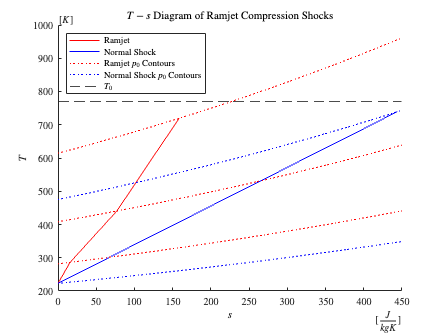

figure;
hold on;

title("$T-s$ Diagram of Ramjet Compression Shocks")

s_plot = plot(s_i, T_i, Color="r", LineStyle="-");
s_norm_plot = plot(s_i_norm, T_i_norm, Color="b", LineStyle="-");
s_contour_plot = plot(s_contour, T_contour_i, Color="r", LineStyle=":");
s_contour_norm_plot = plot(s_contour_norm, T_contour_i_norm, Color="b", LineStyle=":");
T_0_plot = yline(T_0_i(1), Color="k", LineStyle="--");

legend([ s_plot; s_norm_plot; s_contour_plot(1); s_contour_norm_plot(1); T_0_plot ] , { "Ramjet", "Normal Shock", "Ramjet $p_{0}$ Contours", "Normal Shock $p_{0}$ Contours", "$T_{0}$" }, Location="northwest")

xlabel("$s$")
xsecondarylabel("[$\frac{J}{kg K}$]")
ylabel("$T$")
ysecondarylabel("[$K$]")

hold off;

## Problem 4

% Constants
R_air = 287; % J/(kg*K)
gamma_air = 1.4; % unitless

% Given
n = 3; % num shocks
M = zeros(n+1, 1); % unitless
p = zeros(n+1, 1); % Pa
theta = zeros(n, 1); % deg
beta = zeros(2, 1); % deg
nu = zeros(2, 1); % deg

M(1) = 2; % unitless
p(1) = 10e3; % Pa
theta(1) = deg2rad(4); % deg
theta(2) = deg2rad(-8); % deg
theta(3) = deg2rad(4); % deg

% Vars
syms R gamma M_a M_b p_a p_b beta_a beta_b theta_a theta_b nu_a nu_b

### Part A

% Solution
tbm_eqn = tan(theta_a) == 2*cot(beta_a)*(M_a^2*sin(beta_a)^2-1)/(M_a^2*(gamma+cos(2*beta_a))+2)

$$tbm\_eqn = \tan\left(\theta_{a}\right)=\frac{2\,\cot\left(\beta_{a}\right)\,\left({M_{a}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}-1\right)}{\left(\gamma +\cos\left(2\,\beta_{a}\right)\right)\,{M_{a}}^{2}+2}$$

M_eqn = M_b^2 * sin(beta_a-theta_a)^2 == (2+(gamma-1)*M_a^2*sin(beta_a)^2)/(2*gamma*M_a^2*sin(beta_a)^2-(gamma-1))

$$M\_eqn = {M_{b}}^{2}\,{\sin\left(\beta_{a}-\theta_{a}\right)}^{2}=\frac{\left(\gamma -1\right)\,{M_{a}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}+2}{2\,\gamma \,{M_{a}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}-\gamma +1}$$

p_eqn_1 = p_b/p_a == 1+2*gamma/(gamma+1)*(M_a^2*sin(beta_a)^2-1)

$$p\_eqn\_1 = \frac{p_{b}}{p_{a}}=\frac{2\,\gamma \,\left({M_{a}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}-1\right)}{\gamma +1}+1$$

nu_eqn = nu_a == ((gamma+1)/(gamma-1))^(1/2)*atan(((gamma-1)/(gamma+1)*(M_a^2-1))^(1/2))-atan((M_a^2-1)^(1/2))

$$nu\_eqn = \nu_{a}=\mathrm{atan}\left(\sqrt{\frac{\left({M_{a}}^{2}-1\right)\,\left(\gamma -1\right)}{\gamma +1}}\right)\,\sqrt{\frac{\gamma +1}{\gamma -1}}-\mathrm{atan}\left(\sqrt{{M_{a}}^{2}-1}\right)$$

expansion_eqn = theta_b == (nu_b - nu_a)

$$expansion\_eqn = \theta_{b}=\nu_{b}-\nu_{a}$$

p_eqn_2 = p_b/p_a == ((2+(gamma-1)*M_b^2)/(2+(gamma-1)*M_a^2))^(gamma/(gamma-1))

$$p\_eqn\_2 = \frac{p_{b}}{p_{a}}={\left(\frac{\left(\gamma -1\right)\,{M_{b}}^{2}+2}{\left(\gamma -1\right)\,{M_{a}}^{2}+2}\right)}^{\frac{\gamma }{\gamma -1}}$$


beta_soln = solve(subs(tbm_eqn, [ gamma M_a beta_a theta_a ], [ gamma_air M(1) beta_a theta(1) ]), beta_a)+pi;
beta(1) = beta_soln;
M_soln = solve(subs(M_eqn, [ gamma M_a M_b beta_a theta_a ], [ gamma_air M(1) M_b beta(1) theta(1) ]), M_b);
M(2) = M_soln(2);
p_soln = solve(subs(p_eqn_1, [ gamma M_a beta_a p_a p_b ], [ gamma_air M(1) beta(1) p(1) p_b ]), p_b);
p(2) = p_soln;

nu_soln = solve(subs(nu_eqn, [ gamma M_a nu_a ], [ gamma_air M(2) nu_a ]), nu_a);
nu(1) = nu_soln;
nu_soln = solve(subs(expansion_eqn, [ theta_b nu_a nu_b ], [ theta(2) nu(1) nu_b ]), nu_b);
nu(2) = nu_soln;

M_soln = solve(subs(nu_eqn, [ gamma M_a nu_a ], [ gamma_air M_a nu(2) ]), M_a);

M(3) = M_soln;
p_soln = solve(subs(p_eqn_2, [ gamma M_a M_b p_a p_b ], [ gamma_air M(2) M(3) p(2) p_b ]), p_b);
p(3) = p_soln;

beta_soln = solve(subs(tbm_eqn, [ gamma M_a beta_a theta_a ], [ gamma_air M(3) beta_a theta(3) ]), beta_a)+pi;
beta(2) = beta_soln;
M_soln = solve(subs(M_eqn, [ gamma M_a M_b beta_a theta_a ], [ gamma_air M(3) M_b beta(2) theta(3) ]), M_b);
M(4) = M_soln(2);
p_soln = solve(subs(p_eqn_1, [ gamma M_a beta_a p_a p_b ], [ gamma_air M(3) beta(2) p(3) p_b ]), p_b);
p(4) = p_soln;

beta = rad2deg(beta)

beta =    33.3902
   43.4924


theta = rad2deg(theta)

theta =      4
    -8
     4


nu = rad2deg(nu)

nu =    22.3583
   14.3583


M

M =     2.0000
    1.8568
    1.5830
    1.4466


p

p = 1.0e+04 *

    1.0000
    1.2467
    0.8243
    1.0043


### Part B

% Given
n = 3; % num shocks
M_new = zeros(n+1, 1); % unitless
p_new = zeros(n+1, 1); % Pa
theta_new = zeros(n, 1); % deg
beta_new = zeros(2, 1); % deg
nu_new = zeros(2, 1); % deg

M_new(1) = 2; % unitless
p_new(1) = 10e3; % Pa
theta_new(1) = deg2rad(6); % deg
theta_new(2) = deg2rad(-12); % deg
theta_new(3) = deg2rad(6); % deg

% Solution
beta_soln = solve(subs(tbm_eqn, [ gamma M_a beta_a theta_a ], [ gamma_air M_new(1) beta_a theta_new(1) ]), beta_a)+pi;
beta_new(1) = beta_soln;
M_soln = solve(subs(M_eqn, [ gamma M_a M_b beta_a theta_a ], [ gamma_air M_new(1) M_b beta_new(1) theta_new(1) ]), M_b);
M_new(2) = M_soln(2);
p_soln = solve(subs(p_eqn_1, [ gamma M_a beta_a p_a p_b ], [ gamma_air M_new(1) beta_new(1) p_new(1) p_b ]), p_b);
p_new(2) = p_soln;

nu_soln = solve(subs(nu_eqn, [ gamma M_a nu_a ], [ gamma_air M_new(2) nu_a ]), nu_a);
nu_new(1) = nu_soln;
nu_soln = solve(subs(expansion_eqn, [ theta_b nu_a nu_b ], [ theta_new(2) nu_new(1) nu_b ]), nu_b);
nu_new(2) = nu_soln;

M_soln = solve(subs(nu_eqn, [ gamma M_a nu_a ], [ gamma_air M_a nu_new(2) ]), M_a);

M_new(3) = -1*M_soln;
p_soln = solve(subs(p_eqn_2, [ gamma M_a M_b p_a p_b ], [ gamma_air M_new(2) M_new(3) p_new(2) p_b ]), p_b);
p_new(3) = p_soln;

beta_soln = solve(subs(tbm_eqn, [ gamma M_a beta_a theta_a ], [ gamma_air M_new(3) beta_a theta_new(3) ]), beta_a)+pi;
beta_new(2) = beta_soln;
M_soln = solve(subs(M_eqn, [ gamma M_a M_b beta_a theta_a ], [ gamma_air M_new(3) M_b beta_new(2) theta_new(3) ]), M_b);
M_new(4) = M_soln(2);
p_soln = solve(subs(p_eqn_1, [ gamma M_a beta_a p_a p_b ], [ gamma_air M_new(3) beta_new(2) p_new(3) p_b ]), p_b);
p_new(4) = p_soln;

M

M =     2.0000
    1.8568
    1.5830
    1.4466


M_new

M_new =     2.0000
    1.7856
    1.3763
    1.1441


p

p = 1.0e+04 *

    1.0000
    1.2467
    0.8243
    1.0043


p_new

p_new = 1.0e+04 *

    1.0000
    1.3871
    0.7597
    1.0332



cl = (p_new(2)-p(2)+p_new(3)-p(3))/(gamma_air*M(1)^2*p(1))

cl = 0.0135

## Problem 5

% Constants
R_air = 287; % J/(kg*K)
gamma_air = 1.4; % unitless

% Given
M = zeros(2, 1); % unitless
T = zeros(2, 1); % K
v = zeros(2, 1); % m/s
beta = zeros(2, 1); % deg

M(1) = 8; % unitless
T(1) = 220; % K
beta(1) = deg2rad(30); % deg

% Vars
syms R gamma M_a M_b T_a T_b v_a beta_a

### Part A

% Solution
M_eqn = M_b^2 * sin(beta_a)^2 == (2+(gamma-1)*M_a^2*sin(beta_a)^2)/(2*gamma*M_a^2*sin(beta_a)^2-(gamma-1))

$$M\_eqn = {M_{b}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}=\frac{\left(\gamma -1\right)\,{M_{a}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}+2}{2\,\gamma \,{M_{a}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}-\gamma +1}$$

T_eqn = T_b/T_a == (1+2*gamma/(gamma+1)*(M_a^2*sin(beta_a)^2-1))*((2+(gamma-1)*M_a^2*sin(beta_a)^2)/((gamma+1)*M_a^2*sin(beta_a)^2))

$$T\_eqn = \frac{T_{b}}{T_{a}}=\frac{\left(\left(\gamma -1\right)\,{M_{a}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}+2\right)\,\left(\frac{2\,\gamma \,\left({M_{a}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}-1\right)}{\gamma +1}+1\right)}{{M_{a}}^{2}\,{\sin\left(\beta_{a}\right)}^{2}\,\left(\gamma +1\right)}$$

v_eqn = M_a == v_a/(gamma*R*T_a)^(1/2)

$$v\_eqn = M_{a}=\frac{v_{a}}{{\left(R\,T_{a}\,\gamma \right)}^{0.5000}}$$


M_soln = solve(subs(M_eqn, [ gamma M_a M_b beta_a ], [ gamma_air M(1) M_b beta(1) ]), M_b);
M(2) = M_soln(2);

T_soln = solve(subs(T_eqn, [ gamma M_a T_a T_b beta_a ], [ gamma_air M(1) T(1) T_b beta(1) ]), T_b);
T(2) = T_soln;

v_soln = solve(subs(v_eqn, [ R gamma M_a T_a v_a ], [ R_air gamma_air M(1) T(1) v_a ]), v_a);
v(1) = v_soln;
v_soln = solve(subs(v_eqn, [ R gamma M_a T_a v_a ], [ R_air gamma_air M(2) T(2) v_a ]), v_a);
v(2) = v_soln;

M

M =     8.0000
    0.8699


T

T =   220.0000
  890.3125


v_soln = v(1) - v(2)

v_soln = 1.8582e+03

### Part B

% Given
M(2) = 0; % m/s
v(2) = 0; % m/s

% Solution
beta_soln = asin(1/M(1));
beta(2) = beta_soln;

beta = rad2deg(beta)

beta =    30.0000
    7.1808


v_min = (gamma_air*R_air*T(1))^(1/2)*(M(1) - 1)

v_min = 2.0812e+03